xdata = [-10 -5 4 15 20]'

xdata =    -10
    -5
     4
    15
    20


ydata = [-30 25 80 50 -40]'

ydata =    -30
    25
    80
    50
   -40


A =      5    24
    24   766


b =     85
   445


coef =   16.727105101413642
   0.056853103872157


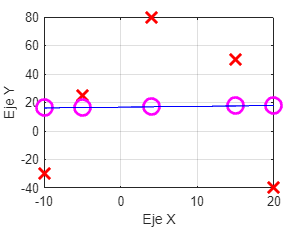

St =        10580


Sr =      1.057789643515673e+04


R2 =      1.988246543733752e-04


M = minimoscuadrados(xdata,ydata);

A =     10    55
    55   385


b = 1.0e+02 *

   0.203300000000000
   1.079800000000000


coef =    2.288666666666668
  -0.046484848484849


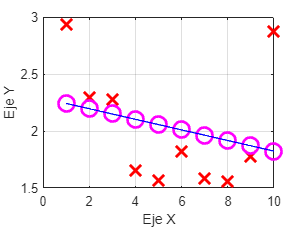

St =    2.531610000000001


Sr =    2.353340606060606


R2 =    0.070417399970530


Y =     10    55
    55   385



t=[1:10]';
precio=[2.93 2.29 2.28 1.65 1.57 1.82 1.58 1.56 1.78 2.87]';

Y = minimoscuadrados(t,precio)

x = [1.1 1.3 2.1 2.4]';
y = [log(1.6) log(1.8) log(3.6) log(6.8)];
b = [sum(y) ; sum(y)*sum(x)]

b =    4.255646751791980
  29.363962587364664


A =    4.000000000000000   6.900000000000000
   6.900000000000000  13.070000000000000


b =    1.880014516982942   2.351146659608476   5.123735381848258   7.667690448728244
   3.243025041795575   4.055727987824621   8.838443533688245  13.226766024056221


coef =    0.470003629245736   0.587786664902119   1.280933845462062   1.916922612182061
                   0                   0   0.000000000000001                   0


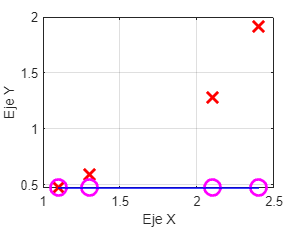

St =    1.354148073476640


Sr =    0.000000000000000   0.055491373953732   2.630431262290648   8.374298172725963


R2 =    1.000000000000000   0.959021191965172  -0.942498987970555  -5.184182023185833


Z =    4.000000000000000   6.900000000000000
   6.900000000000000  13.070000000000000



Z= minimoscuadrados(x,y)

x = inv(M)*b

x =    0.785215215050985
   0.013732111522377


A = 1.0e+03 *

   0.010000000000000   0.267100000000000
   0.267100000000000   7.407010000000001


b = 1.0e+04 *

   0.084522000000000
   2.343228800000000


coef =    0.655817706556815
   3.139879531765001


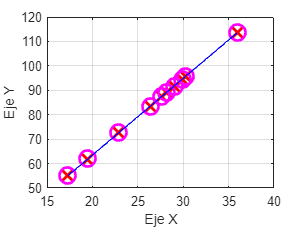

St =      2.689187960000000e+03


Sr =    0.001084441413796


R2 =    0.999999596740194


P = 1.0e+03 *

   0.010000000000000   0.267100000000000
   0.267100000000000   7.407010000000001



x = [17.3 19.5 22.9 26.4 27.6 28.2 29 29.9 30.3 36.0];
y = [55 61.87 72.55 83.54 87.31 89.2 91.71 94.54 95.8 113.7];
P = minimoscuadrados(x,y)

Función ajuste por mínimos cuadrados

function M = minimoscuadrados(xdata,ydata)
    A = [ sum(xdata.^0) sum(xdata.^1)
      sum(xdata.^1) sum(xdata.^2) ]
    b = [ sum((xdata.^0).*ydata)
          sum((xdata.^1).*ydata) ]
    % te da [a0, a1]
    coef = A\b
    % Estimación de la recta:
    yh = coef(1) + coef(2)*xdata;
    
    figure(1); clf;
    xx = xdata(1):0.1:xdata(end);
    yy = coef(1) + coef(2)*xx;
    plot(xdata,ydata,'xr','MarkerSize',12,'LineWidth',2); grid on; hold on;
    plot(xdata,yh,'om','MarkerSize',12,'LineWidth',2);
    plot(xx,yy,'-b'); 
    xlabel('Eje X'); ylabel('Eje Y')
    St = sum((ydata - mean(ydata)).^2)
    Sr = sum((ydata - yh).^2)
    R2 = 1 - Sr/St
    M = A;
end